# ===============================================================

clear; close all; clc;

## ===============================================================

1️⃣ PROBLEM PARAMETERS AND DOMAIN ===============================================================

nNodesX = 6;
nNodesY = 6;
nNodes = nNodesX * nNodesY;

B_min = 1;  B_max = 3;     % base range
H_min = 1;  H_max = 3;     % height range
nSamples = 1000;           % number of geometries for training

% Material (constant)
E = 1;
nu = 0.3;

% Reference unit mesh
[xGrid, yGrid] = meshgrid(linspace(0,1,nNodesX), linspace(0,1,nNodesY)); 
%linspace - generate linearly spaced vectors - linspace(x1,x2,n) generates n points. The spacing between the points is (x2-x1)/(n-1).
coords0 = [xGrid(:), yGrid(:)];

% DOF per node and totals
ndofNode = 2; %2 dof per node, ux and uy
nDOF = nNodes * ndofNode; %72 total system's dof

fprintf('Problem: %d nodes (%dx%d) -> %d DOFs\n', nNodes, nNodesX, nNodesY, nDOF);

Problem: 36 nodes (6x6) -> 72 DOFs


## ===============================================================

2️⃣ DATASET CREATION (FEM) - body force applied to entire plate Base (bottom, y==0) is fixed a priori in dataset and training =============================================================== 

bodyForce = [1; 0]; % Body force per unit volume (fx, fy)
%bodyForce = [0; 1]; 
%bodyForce = [1; 1]; wouldnt work for [2;1]

% Preallocate geometry matrix and outputs (outputs = full displacement vector u)
Xdata = zeros(2, nSamples);   % [B; H]
Uall  = zeros(nDOF, nSamples);% each column is full displacement vector for that sample

fprintf('Generating FEM dataset (%d samples) with base fixed (y==0)...\n', nSamples);

Generating FEM dataset (1000 samples) with base fixed (y==0)...



for i = 1:nSamples
    % random geometric parameters
    B = B_min + (B_max - B_min) * rand(); %rand returns a random scalar drawn from the uniform distribution in the interval (0,1).
    H = H_min + (H_max - H_min) * rand();
    Xdata(:,i) = [B; H];

    % physical coordinates scaled
    coords = [coords0(:,1)*B, coords0(:,2)*H];

    % build FEM stiffness and force
    [K, F] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyForce);

    % identify base nodes (y == 0) -> fixed
    tol = 1e-12;
    baseNodes = find(abs(coords(:,2) - 0) < tol); % bottom side, coords(i,2) → y-coordinate of node i
    %The expression is written in the general mathematical form: ∣𝑦−𝑦0∣<tolerance
    %<tol -> Floating-point numbers are not exact.
    % Even if mathematically a node should be at y = 0, numerically it might be: 1.0e-16
    fixedDOFs = reshape([ (baseNodes-1)'*ndofNode + 1 ; (baseNodes-1)'*ndofNode + 2 ], [], 1);
    %baseNodes is a list of node indices on the bottom edge.
    %baseNodes - 1 shifts node numbers to zero-based indexing
    % ' -> transpose → makes it a row vector. Multiply by ndofNode = 2
    %reshape - Flattens column-wise into a single column vector:
    % reshape([1 3 5; 2 4 6], [], 1)  -- to -- fixedDOFs = [1; 2; 3; 4; 5; 6]

    % free DOFs
    allDOFs = (1:nDOF)';
    freeDOFs = setdiff(allDOFs, fixedDOFs);
    %setdiff(A,B) returns:Elements in A that are NOT in B

    % Solve for displacements: u(free) = K_ff \ F_f
    u = zeros(nDOF,1);
    u(freeDOFs) = K(freeDOFs, freeDOFs) \ F(freeDOFs);
    %\ is a linear solver; u = K-1*F
    % fixed DOFs remain zero by construction

    Uall(:,i) = u;
end

disp('✅ FEM dataset generated.');

✅ FEM dataset generated.


## ===============================================================

3️⃣ DATA PREPARATION AND NORMALIZATION - Input normalization to [-1,1] - Output normalization: z-score per DOF =============================================================== 

%Normalization of NN inputs & outputs - can make training faster and reduce the chances of getting stuck in local optima. 
% Also, weight decay and Bayesian estimation can be done more conveniently with standardized inputs.
% Inputs for neural networks are normalized to ensure the model trains faster, achieves higher accuracy, and remains numerically stable. Without normalization, features with larger magnitudes can dominate the learning process, leading to slow convergence or failure to find an optimal solution. 

%Input normalization to [-1,1]

Bnorm = 2*(Xdata(1,:) - B_min)/(B_max - B_min) - 1;
Hnorm = 2*(Xdata(2,:) - H_min)/(H_max - H_min) - 1;
Xnorm = [Bnorm; Hnorm];
%Xdata(1,:) → all samples of parameter B
%Xdata(2,:) → all samples of parameter H

% Output normalization (z-score) per DOF (row-wise)

epsVal = 1e-8; %numerical safeguard almost zero, but not zero
mu_U = mean(Uall,2); %mean; 2 → along columns
sigma_U = std(Uall,0,2) + epsVal; %standard deviation;
% 0 → unbiased estimator; 2 → row-wise; Add epsVal to avoid zero division
Uall_norm = (Uall - mu_U) ./ sigma_U;
%Standardization consists of subtracting a quantity related to a measure of localization or distance and dividing by a measure of the scale. 
% The best-known example is perhaps the called z-score or standard score:
% x'=\frac{x-\mu}{\sigma}

% Convert to single for speed (optional)
Xn = single(Xnorm);
Un = single(Uall_norm);
%single → 32 bit, 6-7 decimal places; double → 64 bit, 15-16 decimal places

% Create dlarray for input when needed; minibatches will be formed manually
dlXall = dlarray(Xn, "CB"); %????
%This line is about telling MATLAB’s Deep Learning engine how to interpret your data.
% It does not change the data, only its labeling and layout.

## ===============================================================

4️⃣ DEFINE SINGLE NETWORK (mapping 2 -> nDOF) =============================================================== Simple fully-connected network

nOut = nDOF;
layers = [
    featureInputLayer(2,"Normalization","none") %2 input features; "Normalization","none" → because you already normalized manually
    fullyConnectedLayer(64)
    tanhLayer
    fullyConnectedLayer(64)
    tanhLayer
    fullyConnectedLayer(nOut)
    ];
dlnet = dlnetwork(layerGraph(layers)); %build a deep learning network with the layers defined above
%A layer graph specifies the architecture of a neural network as a directed acyclic graph (DAG) of deep learning layers. The layers can have multiple inputs and multiple outputs.

## ===============================================================

5️⃣ TRAINING (minibatch) - manual loop with Adam ===============================================================

numEpochs = 1000;
learnRate = 1e-3; %standard Adam starting value
miniBatchSize = 200;
%Epoch → one full pass over all FEM samples
% Learning rate → step size of parameter updates
% Mini-batch size → number of FEM simulations per gradient step

avgGrad = []; %mean of gradients
avgSqGrad = []; %variance of gradients

numIterationsPerEpoch = ceil(nSamples / miniBatchSize);

disp('🚀 Starting training single network (minibatch Adam)...');

🚀 Starting training single network (minibatch Adam)...



for epoch = 1:numEpochs
    idx = randperm(nSamples);

    for it = 1:numIterationsPerEpoch
        batchStart = (it-1)*miniBatchSize + 1;
        batchEnd = min(it*miniBatchSize, nSamples);
        batchIdx = idx(batchStart:batchEnd);

        % form minibatch
        Xbatch = dlarray(Xn(:,batchIdx), "CB");
        Ybatch = dlarray(Un(:,batchIdx), "CB");

        % compute loss and gradients
        [loss, gradients] = dlfeval(@modelLoss, dlnet, Xbatch, Ybatch);
        %The dlfeval function evaluates deep learning models and functions with automatic differentiation enabled.

        % update network parameters with Adam
        iteration = (epoch-1)*numIterationsPerEpoch + it;
        [dlnet, avgGrad, avgSqGrad] = adamupdate(dlnet, gradients, avgGrad, avgSqGrad, iteration, learnRate);
        %adamupdate - This function applies the Adam optimization algorithm to update network parameters in custom training loops.
        %Use this syntax in a training loop to iteratively update a network defined as a dlnetwork object.
    end

    if mod(epoch,100)==0 || epoch==1 %mod-Remainder after division, print for every multiple of 100 or 1 
        fprintf('Epoch %d/%d - Loss %.3e\n', epoch, numEpochs, gather(extractdata(loss)));
    end

    % optional LR schedule
    if epoch == round(0.7*numEpochs)
        learnRate = learnRate * 0.2;
        fprintf('Learning rate decreased to %.2e at epoch %d\n', learnRate, epoch);
    end
end

Epoch 1/1000 - Loss 7.128e-01
Epoch 100/1000 - Loss 3.185e-03
Epoch 200/1000 - Loss 4.737e-04
Epoch 300/1000 - Loss 7.561e-04
Epoch 400/1000 - Loss 1.847e-04
Epoch 500/1000 - Loss 3.832e-04
Epoch 600/1000 - Loss 9.336e-05
Epoch 700/1000 - Loss 8.667e-05


Learning rate decreased to 2.00e-04 at epoch 700


Epoch 800/1000 - Loss 5.582e-05
Epoch 900/1000 - Loss 5.473e-05
Epoch 1000/1000 - Loss 5.702e-05



disp('✅ Training completed.');

✅ Training completed.



% Save trained network and normalization data
save(['single_net_fullu_', num2str(nNodesX),'x',num2str(nNodesY), '.mat'], ...
    'dlnet','B_min','B_max','H_min','H_max','mu_U','sigma_U', ...
    'nNodesX','nNodesY','E','nu','ndofNode');

## ===============================================================

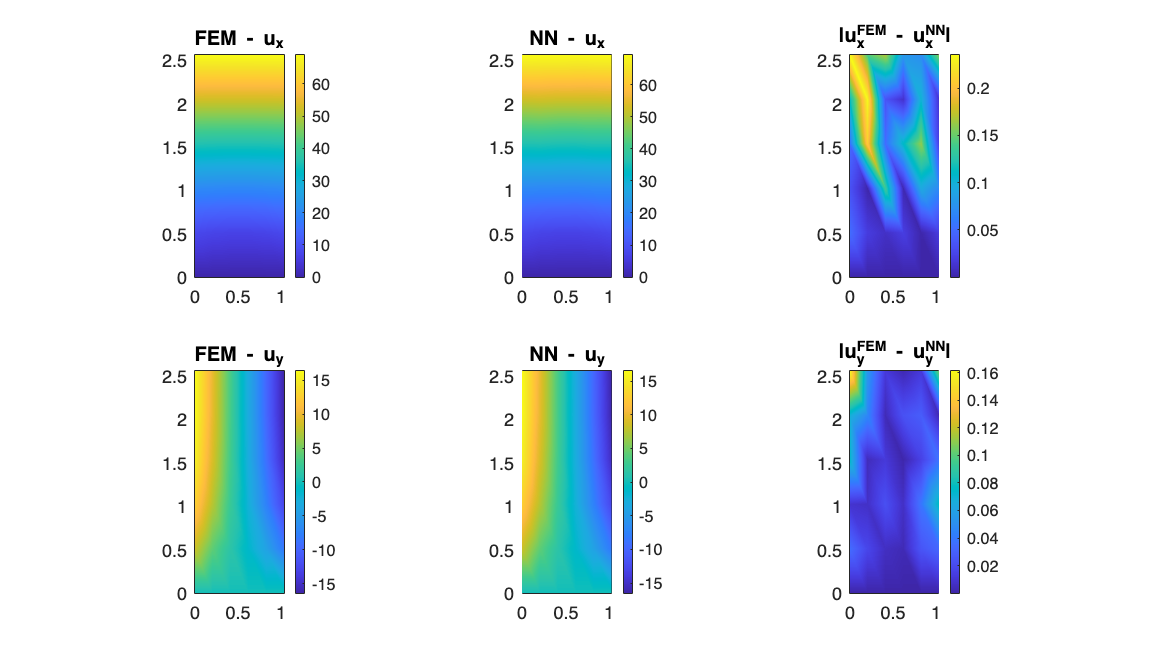

% Btest = 1.25;
% Htest = 2.0;
Btest = 1.03;
Htest = 2.56;

% --- Normalize geometry input ---
Bnorm_t = 2*(Btest - B_min)/(B_max - B_min) - 1;
Hnorm_t = 2*(Htest - H_min)/(H_max - H_min) - 1;
dlGeom = dlarray(single([Bnorm_t; Hnorm_t]), "CB");

% --- Predict normalized u ---
u_norm_dl = predict(dlnet, dlGeom);
u_norm = double(extractdata(u_norm_dl));

% --- De-normalize to physical scale ---
u_pred = (u_norm .* mu_U*0 + 0); % placeholder
% Note: careful broadcasting: u_norm is (nOut x 1), mu_U and sigma_U are (nOut x 1)
u_pred = (u_norm .* sigma_U) + mu_U;

% --- FEM solution for the same geometry (base fixed) ---
coords = [coords0(:,1)*Btest, coords0(:,2)*Htest];
[K, F] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyForce);

% apply base fixed BC (y==0)
tol = 1e-12;
baseNodes = find(abs(coords(:,2) - 0) < tol);
fixedDOFs = reshape([ (baseNodes-1)'*ndofNode + 1 ; (baseNodes-1)'*ndofNode + 2 ], [], 1);
allDOFs = (1:nDOF)';
freeDOFs = setdiff(allDOFs, fixedDOFs);

u_fem = zeros(nDOF,1);
u_fem(freeDOFs) = K(freeDOFs, freeDOFs) \ F(freeDOFs);

% --- Compare FEM vs NN ---
u_NN = u_pred(:);
u_FEM = u_fem(:);

% extract u_x and u_y components
u_x_FEM = u_FEM(1:2:end);
u_y_FEM = u_FEM(2:2:end);
u_x_NN  = u_NN(1:2:end);
u_y_NN  = u_NN(2:2:end);

% reshape on grid
Xcoords = reshape(coords(:,1), nNodesY, nNodesX);
Ycoords = reshape(coords(:,2), nNodesY, nNodesX);

UxF = reshape(u_x_FEM, nNodesY, nNodesX);
UyF = reshape(u_y_FEM, nNodesY, nNodesX);
UxN = reshape(u_x_NN,  nNodesY, nNodesX);
UyN = reshape(u_y_NN,  nNodesY, nNodesX);

Err_u = abs(UxF - UxN);
Err_v = abs(UyF - UyN);

figure('Position',[100 100 1400 800]);

subplot(2,3,1);
pcolor(Xcoords, Ycoords, UxF); shading interp; colorbar; axis equal tight;
title('FEM - u_x');

subplot(2,3,2);
pcolor(Xcoords, Ycoords, UxN); shading interp; colorbar; axis equal tight;
title('NN - u_x');

subplot(2,3,3);
pcolor(Xcoords, Ycoords, Err_u); shading interp; colorbar; axis equal tight;
title('|u_x^{FEM} - u_x^{NN}|');

subplot(2,3,4);
pcolor(Xcoords, Ycoords, UyF); shading interp; colorbar; axis equal tight;
title('FEM - u_y');

subplot(2,3,5);
pcolor(Xcoords, Ycoords, UyN); shading interp; colorbar; axis equal tight;
title('NN - u_y');

subplot(2,3,6);
pcolor(Xcoords, Ycoords, Err_v); shading interp; colorbar; axis equal tight;
title('|u_y^{FEM} - u_y^{NN}|');


% Errors
err_vec = u_FEM - u_NN;
e = err_vec;
u_ref = u_FEM;

RMSE = norm(e) / sqrt(numel(e));
relL2 = norm(e) / norm(u_ref);
maxErr = norm(e, Inf) / norm(u_ref, Inf);

fprintf('RMSE (internal nodes, v)      : %.3e\n', RMSE);

RMSE (internal nodes, v)      : 7.540e-02


fprintf('Relative L2 error (internal nodes, v)  : %.3e\n', relL2);

Relative L2 error (internal nodes, v)  : 2.651e-03


fprintf('Relative Infinity norm error (internal nodes, v)      : %.3e\n', maxErr); %maximum error

Relative Infinity norm error (internal nodes, v)      : 3.405e-03


disp('✅ Verification completed.');

✅ Verification completed.


## ===============================================================

Local functions 

===============================================================

function [K,F] = buildPlaneStressFEM(coords,nx,ny,E,nu,bodyForce)
% Structured mesh of 4-node bilinear quadrilateral elements
nNodes = nx*ny;
nElemX = nx-1; nElemY = ny-1;
nElem = nElemX * nElemY;
ndofNode = 2;
nDOF = nNodes * ndofNode; %total dof of system

% element connectivity matrix
%(ix, iy) is one quadrilateral element
conn = zeros(nElem,4);
for ix = 1:nElemX
    for jy = 1:nElemY
        n1 = (ix-1)*ny + jy;
        n2 = ix*ny + jy;
        n3 = ix*ny + (jy+1);
        n4 = (ix-1)*ny + (jy+1);
        e = (ix-1)*nElemY + jy; %This converts the 2D element index (ix, jy) into a single element number
        conn(e,:) = [n1 n2 n3 n4]; %Element e connects nodes n1, n2, n3, n4
    end
end

K = zeros(nDOF);
F = zeros(nDOF,1);

% Plane stress constitutive matrix
D = E / (1 - nu^2) * [1, nu, 0;
    nu, 1, 0;
    0, 0, (1-nu)/2];

% 2x2 Gauss
gp = [-1/sqrt(3), 1/sqrt(3)];
wgp = [1,1];

for e = 1:nElem
    nodes = conn(e,:);
    xe = coords(nodes,1);
    ye = coords(nodes,2);

    %element stiffness and force matrix
    Ke = zeros(8,8);
    Fe = zeros(8,1);

    % Reduced integration term B0 for shear (as in original)
    xi = 0; eta = 0;
    [N0, dNdxi0, dNdeta0] = shape4(xi,eta);
    J0 = [dNdxi0'; dNdeta0'] * [xe, ye];
    detJ0 = det(J0);
    invJ0 = inv(J0);
    dN0 = [dNdxi0, dNdeta0] * invJ0;

    B0 = zeros(3,8);
    for a = 1:4
        dNx = dN0(a,1);
        dNy = dN0(a,2);
        col = (a-1)*2;
        B0(1, col + 1) = dNx;
        B0(2, col + 2) = dNy;
        B0(3, col + 1) = dNy;
        B0(3, col + 2) = dNx;
    end

    for i = 1:2
        for j = 1:2
            xi = gp(i); eta = gp(j);
            [N, dNdxi, dNdeta] = shape4(xi,eta);
            J = [dNdxi'; dNdeta'] * [xe, ye];
            detJ = det(J);
            invJ = inv(J);
            dN = [dNdxi, dNdeta] * invJ;

            B = zeros(3,8);
            for a = 1:4
                dNx = dN(a,1);
                dNy = dN(a,2);
                col = (a-1)*2;
                B(1, col + 1) = dNx;
                B(2, col + 2) = dNy;
                B(3, col + 1) = dNy;
                B(3, col + 2) = dNx;
            end

            % replace shear row with reduced B0 shear row
            B(3,:) = B0(3,:);

            Ke = Ke + (B' * D * B) * detJ * wgp(i) * wgp(j);

            Nmat = zeros(2,8);
            for a = 1:4
                Nmat(1, (a-1)*2 + 1) = N(a);
                Nmat(2, (a-1)*2 + 2) = N(a);
            end
            Fe = Fe + (Nmat' * bodyForce) * detJ * wgp(i) * wgp(j);
        end
    end

    % assemble
    gdofs = zeros(8,1);
    for a = 1:4
        node = nodes(a);
        gdofs((a-1)*2 + (1:2)) = (node-1)*2 + (1:2);
    end
    K(gdofs, gdofs) = K(gdofs, gdofs) + Ke;
    F(gdofs) = F(gdofs) + Fe;
end
end

function [N, dNdxi, dNdeta] = shape4(xi,eta)
N = 0.25*[(1-xi)*(1-eta);
    (1+xi)*(1-eta);
    (1+xi)*(1+eta);
    (1-xi)*(1+eta)];
dNdxi  = 0.25*[-(1-eta); (1-eta); (1+eta); -(1+eta)];
dNdeta = 0.25*[-(1-xi); -(1+xi); (1+xi);  (1-xi)];
end

function [loss,gradients] = modelLoss(dlnet,X,Y)
% Simple MSE loss for single network
Ypred = forward(dlnet,X);
loss = mean((Ypred - Y).^2,'all');
gradients = dlgradient(loss, dlnet.Learnables);
end